syms v p

equ = 0.26682 + 0.00918261 * p + 4.8841 * 10^-7 * v * p -1.711* 10^-5 * p^2

$$equ = \frac{1323353567177235\,p}{144115188075855872}+\frac{4612902027796727\,p\,v}{9444732965739290427392}-\frac{5049980657618727\,p^{2}}{295147905179352825856}+\frac{13341}{50000}$$


bot = solve(equ == 1.20, p);
top = solve(equ == 1.95, p);
mid = solve(equ == 1.65, p);
format short
botp(v) = vpa(bot(1), 2);
topp(v) = vpa(top(1), 2)

$$topp(v) = 0.014272647575126029551029205322266\,v-29222.67679595947265625\,\sqrt{0.00000000000023854432811099032080669191113742\,v^{2}+0.000000008969757100268926919284240284469\,v-0.000030876512788324816938256844878197}+268.34044420719146728515625$$

midp(v) = vpa(mid(1), 2);

L = 1

L = 1

k = 0.000694

k = 6.9400e-04

v_0 = 4500

v_0 = 4500

logistic(v) = L / (1 + exp(-k * (v - v_0)))

$$logistic(v) = \frac{1}{{\mathrm{e}}^{\frac{3600573858887182875}{1152921504606846976}-\frac{3200510096788607\,v}{4611686018427387904}}+1}$$

modified(v) = botp(v) * logistic(v) + topp(v) * (1 - logistic(v))

$$modified(v) = \frac{0.014272647575126029551029205322266\,v-29222.67679595947265625\,\sqrt{0.00000000000023854432811099032080669191113742\,v^{2}+0.000000008969757100268926919284240284469\,v+0.000020453487213245580278453417122364}+268.34044420719146728515625}{{\mathrm{e}}^{\frac{3600573858887182875}{1152921504606846976}-\frac{3200510096788607\,v}{4611686018427387904}}+1}-\left(\frac{1}{{\mathrm{e}}^{\frac{3600573858887182875}{1152921504606846976}-\frac{3200510096788607\,v}{4611686018427387904}}+1}-1\right)\,\left(0.014272647575126029551029205322266\,v-29222.67679595947265625\,\sqrt{0.00000000000023854432811099032080669191113742\,v^{2}+0.000000008969757100268926919284240284469\,v-0.000030876512788324816938256844878197}+268.34044420719146728515625\right)$$


double(modified(6500))

ans = 104.9485


xbot = linspace(2000, 7000, 100)

xbot = 	1.0e+03 *

    2.0000    2.0505    2.1010    2.1515    2.2020    2.2525    2.3030    2.3535    2.4040    2.4545    2.5051    2.5556    2.6061    2.6566    2.7071    2.7576    2.8081    2.8586    2.9091    2.9596    3.0101    3.0606    3.1111    3.1616    3.2121    3.2626    3.3131    3.3636    3.4141    3.4646    3.5152    3.5657    3.6162    3.6667    3.7172    3.7677    3.8182    3.8687    3.9192    3.9697    4.0202    4.0707    4.1212    4.1717    4.2222    4.2727    4.3232    4.3737    4.4242    4.4747


xtop = linspace(2402, 7000, 100)

xtop = 	1.0e+03 *

    2.4020    2.4484    2.4949    2.5413    2.5878    2.6342    2.6807    2.7271    2.7736    2.8200    2.8664    2.9129    2.9593    3.0058    3.0522    3.0987    3.1451    3.1916    3.2380    3.2844    3.3309    3.3773    3.4238    3.4702    3.5167    3.5631    3.6096    3.6560    3.7024    3.7489    3.7953    3.8418    3.8882    3.9347    3.9811    4.0276    4.0740    4.1204    4.1669    4.2133    4.2598    4.3062    4.3527    4.3991    4.4456    4.4920    4.5384    4.5849    4.6313    4.6778


hold on
plot(xtop, topp(xtop))

plot(xbot, modified(xtop))

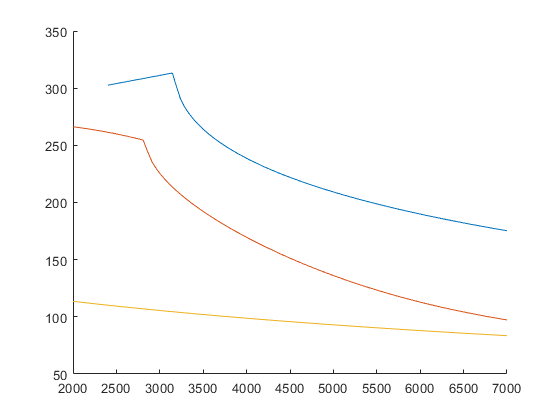

1.95plot(xbot, botp(xbot))

%plot(xbot, midp(xbot))